# Replace Slide Content

Use the `replace` method of an `mlreportgen.ppt.Slide` object to replace placeholder content with your content.

Import the PPT package so that you do not have to use long, fully qualified names for the PPT API classes.

import mlreportgen.ppt.*

Create a presentation. Add a slide for text, a slide for a  picture, and a slide for a table.

ppt = Presentation('mySlideReplacePresentation.pptx');
slide1 = add(ppt,'Title and Content');
slide2 = add(ppt,'Title and Picture');
slide3 = add(ppt,'Title and Table');

In the first slide, replace the `Title` and `Content` placeholders with text.

replace(slide1,'Title','Text Slide');
replace(slide1,'Content','This is the content for slide 1');

In the second slide, replace the `Title` placeholder with text and the `Picture` placeholder with a picture.

replace(slide2,'Title','Picture Slide');
replace(slide2,'Picture',Picture('b747.jpg'));

In the third slide, replace the `Title` placeholder with text and the `Table` placeholder with a table.

replace(slide3,'Title','Table Slide');
replace(slide3,'Table',Table({1 2; 'a' 'b'}));

Close and view the presentation.

close(ppt);
rptview(ppt);

Here is the generated presentation:

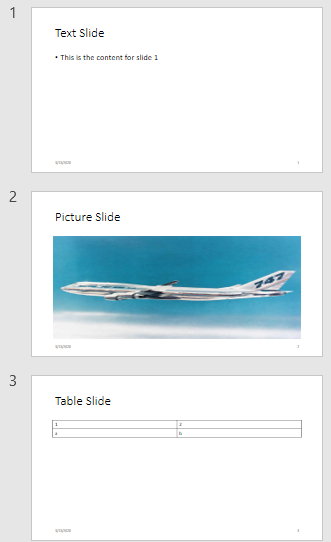

*Copyright 2020 The MathWorks, Inc.*